% This script can take the data from trackman then calculate
% and plot an approximate instantaneous baseball position on the path
% of its pitch trajectory as well as the seam orientation, spin axis, 
% velocity vector, the hemisphere plane, and the active zone.
% It also calculates the seam orientation relative to the velocity vector
% for seam shifted wake research

% Coordinate System Specifications:
% The origin is at the tip of the home plate
% The positive y axis points to the pitcher
% The positive x axis points to the right of catcher's perspective
% The positive z axis points to the sky


% Define variables (feet)
PLATEYDIM = 17.0/12.0; % Front of the plate
ball_radius = 0.125; % Radius of a regular baseball
diameter = 2*ball_radius; % Get ball diameter
diameter2 = 2*diameter; % Get 2*diameter


% Input initial baseball position (feet)
relSide = 0.029947806; % Positive relSide is in the -x direction
releaseDistance = 54.91638133;
release_pos_y = releaseDistance;
relHeight = 6.67789545;

% Input the 9-parameter model (feet and seconds)
x0 = 0.154408881;
y0 = 50;
z0 = 6.485019981;
vx0 = 0.828404718;
vy0 = -134.6288521;
vz0 = -5.574984195;
ax0 = -7.247916794;
ay0 = 31.19727834;
az0 = -14.8795846;

% Input spin axis (unit vector)
a1 = 0;
a2 = 0;
a3 = -1;

% Handle exception
if ((a1^2 + a2^2 + a3^2) > 1.01 || (a1^2 + a2^2 + a3^2) < 0.99)
    ME = MException('myComponent:inputError', 'Please enter a unit vector.');
    throw(ME);
end

% Input spin rate (RPM)
spin_rate = 1200;

% Input seam angles (degrees)
lat_d = 30;
long_d = 0;


% Calculate the position of the ball as a function of time using equations of motion
% To do: Change it to a more appropriate model

% This part is modified from Professor Glenn Healey's code
% Compute time in seconds for baseball to travel from y=release_pos_y to y=y0
% Note that t1 is negative
% Solves equation release_pos_y - y0 = vy0*t1 + 0.5*ay0*t1*t1
t1 = (-vy0 - sqrt(vy0*vy0 - 2.0*ay0*(y0 - release_pos_y)))/ay0;

% Solve for position and velocity at release point (y0 = release_pos_y) in units of feet and seconds */
TM_x0 = 0.5*ax0*t1*t1 + vx0*t1 + x0;
TM_y0 = 0.5*ay0*t1*t1 + vy0*t1 + y0;
TM_z0 = 0.5*az0*t1*t1 + vz0*t1 + z0;
TM_vx0 = vx0 + ax0*t1;
TM_vy0 = vy0 + ay0*t1;
TM_vz0 = vz0 + az0*t1;

% Compute time in seconds for baseball to travel from y=release_pos_y to front of plate (y=1.417) */
t2 = (-TM_vy0 - sqrt(TM_vy0*TM_vy0 - 2.0*ay0*(TM_y0 - PLATEYDIM)))/ay0;

% Input time (sec)
time = 0;

% Compute (x,y,z) position of pitch as function of time (ft)
baseballx = TM_x0 + TM_vx0*time + 0.5*ax0*time*time;
basebally = TM_y0 + TM_vy0*time + 0.5*ay0*time*time;
baseballz = TM_z0 + TM_vz0*time + 0.5*az0*time*time;
fprintf('t = %f, x = %f, y = %f, z = %f\n', time, baseballx, basebally, baseballz); 

t = 0.000000, x = 0.119492, y = 54.916381, z = 6.677915



position_x = baseballx;
position_y = basebally;
position_z = baseballz;
center = [position_x position_y position_z]; % Baseball center

% Calculate the velocity vector as a function of time (ft/sec)
velocity_x = TM_vx0 + ax0*time;
velocity_y = TM_vy0 + ay0*time;
velocity_z = TM_vz0 + az0*time;
v_vector = [velocity_x velocity_y velocity_z];
fprintf('vx = %f, vy = %f, vz = %f\n', velocity_x, velocity_y, velocity_z); 

vx = 1.091974, vy = -135.763335, vz = -5.033891



% Normalize
v_vector = v_vector./norm(v_vector);


% Calculate the hemisphere plane using equation of a plane: ax+by+cz=d
d = v_vector(1)*center(1) + v_vector(2)*center(2) + v_vector(3)*center(3);
xd = linspace(center(1) - diameter2, center(1) + diameter2);
yd = linspace(center(2) - diameter2, center(2) + diameter2);
[hemisphere_x, hemisphere_y] = meshgrid(xd, yd);
hemisphere_z = (d - (v_vector(1).*hemisphere_x + v_vector(2).*hemisphere_y))./v_vector(3); % Solve for z vertices data
fprintf('hemisphere plane equation: %fx + %fy + %fz = %f\n', v_vector(1), v_vector(2), v_vector(3), d); % Print the equation

hemisphere plane equation: 0.008037x + -0.999281y + -0.037052z = -55.123366




% Calculate the angle needed for the ball to rotate around the spin axis based on spin
% rate and time (degrees)
rotation_angle = mod((spin_rate*360/60)*time, 360);
fprintf('spin axis rotation (theta alpha) = %f degrees\n', rotation_angle); 

spin axis rotation (theta alpha) = 0.000000 degrees


theta_alpha_d = rotation_angle;

% Calculate the basis of baseball frame (for seam orientation):
% This is based on the paper 'How to uniquely specify a pitched baseball's
% seam orientation'

% Handle corner case when seam lat = 0
% Set theta alpha = seam long and set seam long to 0 in this case
if lat_d == 0
   theta_alpha_d = long_d;
   long_d = 0;
end

% Convert to radians
lat = lat_d*pi/180.0;
long = long_d*pi/180.0;
theta_alpha = theta_alpha_d*pi/180.0;

% Define rotation matrices
Rlat = [ cos(lat), -sin(lat), 0;
         sin(lat),  cos(lat), 0;
                0,         0, 1];

Rlong = [  cos(long), 0, sin(long);
                   0, 1,         0;
          -sin(long), 0, cos(long)];

Ralpha = [  cos(theta_alpha), 0, sin(theta_alpha);
                           0, 1,                0;
           -sin(theta_alpha), 0, cos(theta_alpha)];

% Calculate theta k and k vector based on spin axis
if a2 == 1
    k = 0;
    Rk = eye(3); % special case, k is undefined, Rk not needed
    k_vector = [1 1 1]; % Use a random vector for k_vector since undefined
elseif a2 == -1
    k = pi;
    % Another special case, k is undefined, rotate around z axis for pi
    Rk = [ cos(k), -sin(k), 0;
           sin(k),  cos(k), 0;
                0,       0, 1];
    k_vector = [0 0 1]; % Make k_vector z axis 
else
    if a2 >= 0
        k = asin(sqrt(a3^2 + a1^2));
        k_vector = [a3/(a1^2 + a3^2)^(1/2), 0, -a1/(a1^2 + a3^2)^(1/2)];
    elseif a2 < 0
        k = pi - asin(sqrt(a3^2 + a1^2));
        k_vector = [a3/(a1^2 + a3^2)^(1/2), 0, -a1/(a1^2 + a3^2)^(1/2)];
    end
    
    % Rotation matrix for Rk
    k1 = k_vector(1);
    k2 = k_vector(2);
    k3 = k_vector(3);
    
    Rk = [  cos(k) + (k1^2)*(1 - cos(k)),   k1*k2*(1 - cos(k)) - k3*sin(k), k1*k3*(1 - cos(k)) + k2*sin(k);
            k2*k1*(1 - cos(k)) + k3*sin(k),   cos(k) + (k2^2)*(1 - cos(k)), k2*k3*(1 - cos(k)) - k1*sin(k);
            k3*k1*(1 - cos(k)) - k2*sin(k), k3*k2*(1 - cos(k)) + k1*sin(k),  cos(k) + (k3^2)*(1 - cos(k))];
end

% Calculate for seam rotations on the ball
temp = Rk*Rlat;
y2 = temp(:, 2); % Rotation axis for seam long
z1 = Rk(:, 3); % Rotation axis for seam lat
k_d = k*180/pi; % Convert k to degrees
spin_axis = [a1 a2 a3]; % Get spin axis

% Define the equation for basis of standard seam orientation
P4 = Rk*Ralpha*Rlat*Rlong;


% Calculate seam lat, seam long, and theta alpha relative to the velocity
% vectors. Use the reverse calculations to obtain the seam angles, but
% replace spin axis with unit velocity vector.
% Note that theta alpha is the third rotation around the velocity vector
% It is there for calculations and reference and it can be ignored.

% Get the components of the velocity vector
v1 = v_vector(1);
v2 = v_vector(2);
v3 = v_vector(3);

% Calculate theta k based on velocity vector
if v2 == 1
    k_v = 0;
    Rk_v = eye(3); % special case, k is undefined, Rk_v not needed
elseif v2 == -1
    k_v = pi;
    % another special case, k is undefined, rotate around z axis for pi
    Rk_v = [ cos(k_v), -sin(k_v), 0;
             sin(k_v),  cos(k_v), 0;
                    0,         0, 1];
else
    if v2 >= 0
        k_v = asin(sqrt(v3^2 + v1^2));
    elseif v2 < 0
        k_v = pi - asin(sqrt(v3^2 + v1^2));
    end

    % Define rotation matrice Rk_v for velocity vector
    Rk_v = [ cos(k_v) - (v3^2*(cos(k_v) - 1))/(v1^2 + v3^2), (v1*sin(k_v))/(v1^2 + v3^2)^(1/2),         (v1*v3*(cos(k_v) - 1))/(v1^2 + v3^2);
                         -(v1*sin(k_v))/(v1^2 + v3^2)^(1/2),                          cos(k_v),           -(v3*sin(k_v))/(v1^2 + v3^2)^(1/2);
                       (v1*v3*(cos(k_v) - 1))/(v1^2 + v3^2), (v3*sin(k_v))/(v1^2 + v3^2)^(1/2), cos(k_v) - (v1^2*(cos(k_v) - 1))/(v1^2 + v3^2)];
end

% Define texture degeneracy matrices
% We need these since there are no markings on the baseball
% Obtain the angles with the minimum sum of seam lat and seam long
Rd = cell(3);

Rd{1} = eye(3);

Rd{2} = [-1 0  0;
          0 1  0;
          0 0 -1];

Rd{3} = [ 0  0 1;
          0 -1 0;
          1  0 0];

Rd{4} = [ 0  0 -1;
          0 -1  0;
         -1  0  0];

% Execute the reverse calculations
e1_v = vpa(Rk_v); % Get the basis of the observer frame
P5 = P4; % Frame 5 will actually be the frame 4 obtained previously

% Use a for-loop for texture degeneracies calculation
lat_v_final = pi;
long_v_final = 2*pi;
alpha_v_final = 0;
min_sum = lat_v_final + long_v_final; % Use the maximum possible sum of seam lat and seam long as the initial value

for j = 1:4
    e4_v = P5*transpose(Rd{j}); % Use equation e4 = P5*(transpose of Rdj) to get frame 4

    z1_v = e1_v(:, 3);
    y4_v = e4_v(:, 2);
    x1_v = e1_v(:, 1);

    % Get theta alpha relative to velocity vector
    alpha_v = vpa(-atan2(dot(y4_v, -z1_v), dot(y4_v, -x1_v)));

    % Make sure theta alpha is positive
    if alpha_v < 0
        alpha_v = 2*pi + alpha_v;
    end

    alpha_v_prime = -alpha_v;
    
    % Define rotation matrice Ralpha_v for velocity vector
    Ralpha_v = [  cos(alpha_v_prime), 0, sin(alpha_v_prime);
                                   0, 1,                  0;
                 -sin(alpha_v_prime), 0, cos(alpha_v_prime)];
    
    e3_v = e1_v*Ralpha_v*transpose(e1_v)*e4_v; % Get the basis of frame 3, e3 = e1*Ry(-theta_alpha)*e4
    x3_v = e3_v(:, 1);
    z3_v = e3_v(:, 3);

    % Get seam long relative to velocity vector
    long_v = vpa(-atan2(dot(x3_v, z1_v), dot(z3_v, z1_v)));
    
    % Make sure seam long is positive
    if long_v < 0
        long_v = 2*pi + long_v;
    end
    
    long_v_prime = -long_v;
    
    % Define rotation matrice Rlong_v for velocity vector
    Rlong_v = [  cos(long_v_prime), 0, sin(long_v_prime);
                                 0, 1,                 0;
                -sin(long_v_prime), 0, cos(long_v_prime)];
    
    e2_v = e3_v*Rlong_v; % Get the basis of frame 2, e2 = e3*Ry(-seam long)
    
    y1_v = e1_v(:, 2);
    y2_v = e2_v(:, 2);

    % Get seam lat relative to velocity vector
    lat_v = vpa(-atan2(dot(y2_v, x1_v), dot(y2_v, y1_v)));

    % Calculate the sum of seam lat and seam long
    sum = lat_v + long_v;

    % Check and see if this is the minimum
    if sum < min_sum
        min_sum = sum;
        lat_v_final = lat_v;
        long_v_final = long_v;
        alpha_v_final = alpha_v;
    end
end

% Convert to degrees and output
alpha_v_final = vpa(alpha_v_final*180/pi); 
lat_v_final = vpa(lat_v_final*180/pi);
long_v_final = vpa(long_v_final*180/pi);
fprintf("seam lat relative to velocity vector = %f degrees\n", lat_v_final);

seam lat relative to velocity vector = 88.391550 degrees


fprintf("seam long relative to velocity vector = %f degrees\n", long_v_final);

seam long relative to velocity vector = 91.461003 degrees


fprintf("theta alpha relative to velocity vector = %f degrees\n", alpha_v_final);

theta alpha relative to velocity vector = 35.501034 degrees


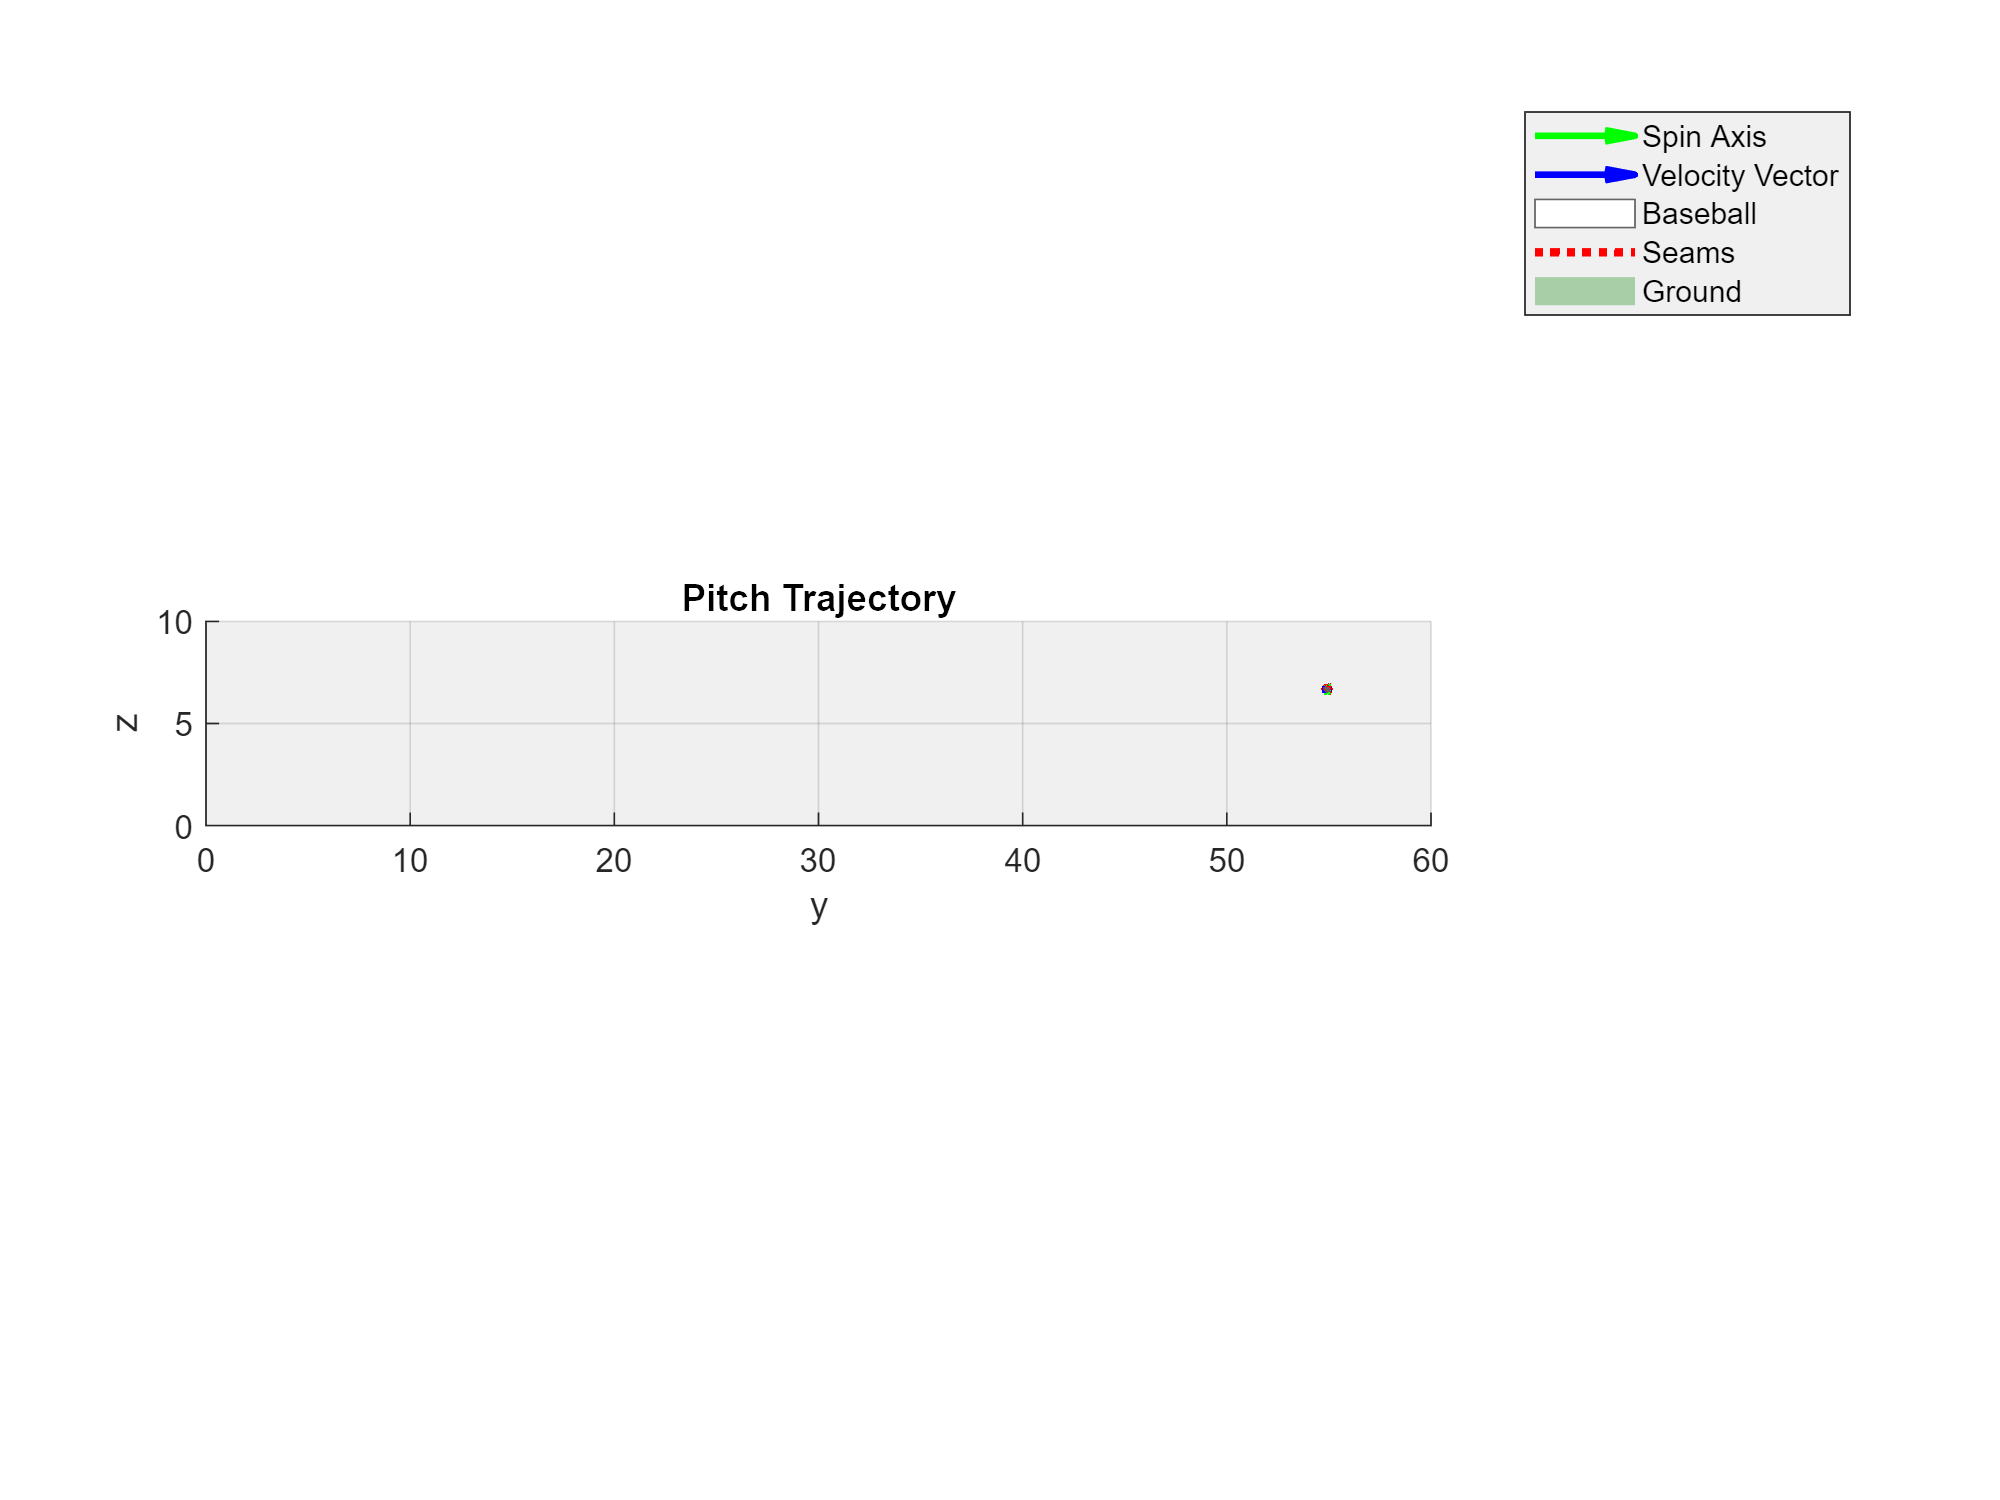



% Plot:
figure
hold on

% Draw spin axis
quiver3(center(1) - a1*diameter, center(2) - a2*diameter, center(3) - a3*diameter, a1, a2, a3, diameter2, 'g', 'LineWidth', 2); % scale the starting point according to ball_radius

% Draw velocity vector
quiver3(center(1) - v_vector(1)*diameter, center(2) - v_vector(2)*diameter, center(3) - v_vector(3)*diameter, v_vector(1), v_vector(2), v_vector(3), diameter2, 'b', 'LineWidth', 2);

% Draw a sphere representing baseball
[X,Y,Z] = sphere(40);

% Account for axes offset
% baseballx = y, basebally = z, baseballz = x
% Also rotate to align the axes
ballx = Y;
bally = Z;
ballz = X;

s = surf(double(center(1) + ball_radius*ballx), double(center(2) + ball_radius*bally), double(center(3) + ball_radius*ballz));
s.FaceColor = 'white'; % Ball color
s.EdgeColor = [100/255 100/255 100/255]; % Grid color
s.FaceAlpha = 1.0; % Transparency

% Rotate the ball to the seam orientation to match the grid
rotate(s, k_vector, k_d, center);
rotate(s, z1, lat_d, center);
rotate(s, y2, long_d, center);
rotate(s, spin_axis, theta_alpha_d, center);

% Draw seams
% The equation of seam line is from 
% http://www.darenscotwilson.com/spec/bbseam/bbseam.html.
alpha = 1:1:360;
% Convert to radian
alpha_r = alpha*pi/180.0;

% Calculate seam points
seamx = (1/13)*ball_radius*(9*cos(alpha_r) - 4*cos(3*alpha_r));
seamy = (1/13)*ball_radius*(9*sin(alpha_r) + 4*sin(3*alpha_r));
seamz = (12/13)*ball_radius*cos(2*alpha_r);

% Account for axes offset
% baseballx = y, basebally = z, baseballz = x
% Also rotate to align the axes
adjustedx = seamy;
adjustedy = seamz;
adjustedz = seamx;

seam_line = [adjustedx; adjustedy; adjustedz];
seam_line = P4*seam_line; % Rotate to the basis

% Add to the ball position
seamx = center(1) + seam_line(1, :);
seamy = center(2) + seam_line(2, :);
seamz = center(3) + seam_line(3, :);

% Plot seam line
p = plot3(seamx, seamy, seamz, '-r', 'LineWidth', 2.5);
p.LineStyle = ':';


% Label and adjust settings
xlabel('x')
ylabel('y')
zlabel('z')
grid on
title('Pitch Trajectory')
set(gca,'color', [240/255 240/255 240/255]) % Background color
axis equal

% Adjust view
view_azimuth = 90;
view_elevation =  0;
view([view_azimuth view_elevation]) % View (default is pitcher's perspective)
axis([-2 2 0 60 0 10]) % Fix the axes

% Adjust figure size
figure_x0 = 10;
figure_y0 = 10;
width = 825;
height = 600;
set(gcf, 'position', [figure_x0, figure_y0, width, height]);

% Change the color of the x-y plane to be dark green
x_lim = get(gca, 'XLim');
y_lim = get(gca, 'YLim');
z_lim = get(gca, 'YLim');
pat = patch([x_lim(1), x_lim(2), x_lim(2), x_lim(1)], [y_lim(1), y_lim(1), y_lim(2), y_lim(2)], [z_lim(1) z_lim(1) z_lim(1) z_lim(1)], [0 0.5 0]);
pat.EdgeColor = 'none';
pat.FaceAlpha = 0.3;

% Label
legend('Spin Axis', 'Velocity Vector', 'Baseball', 'Seams', 'Ground')

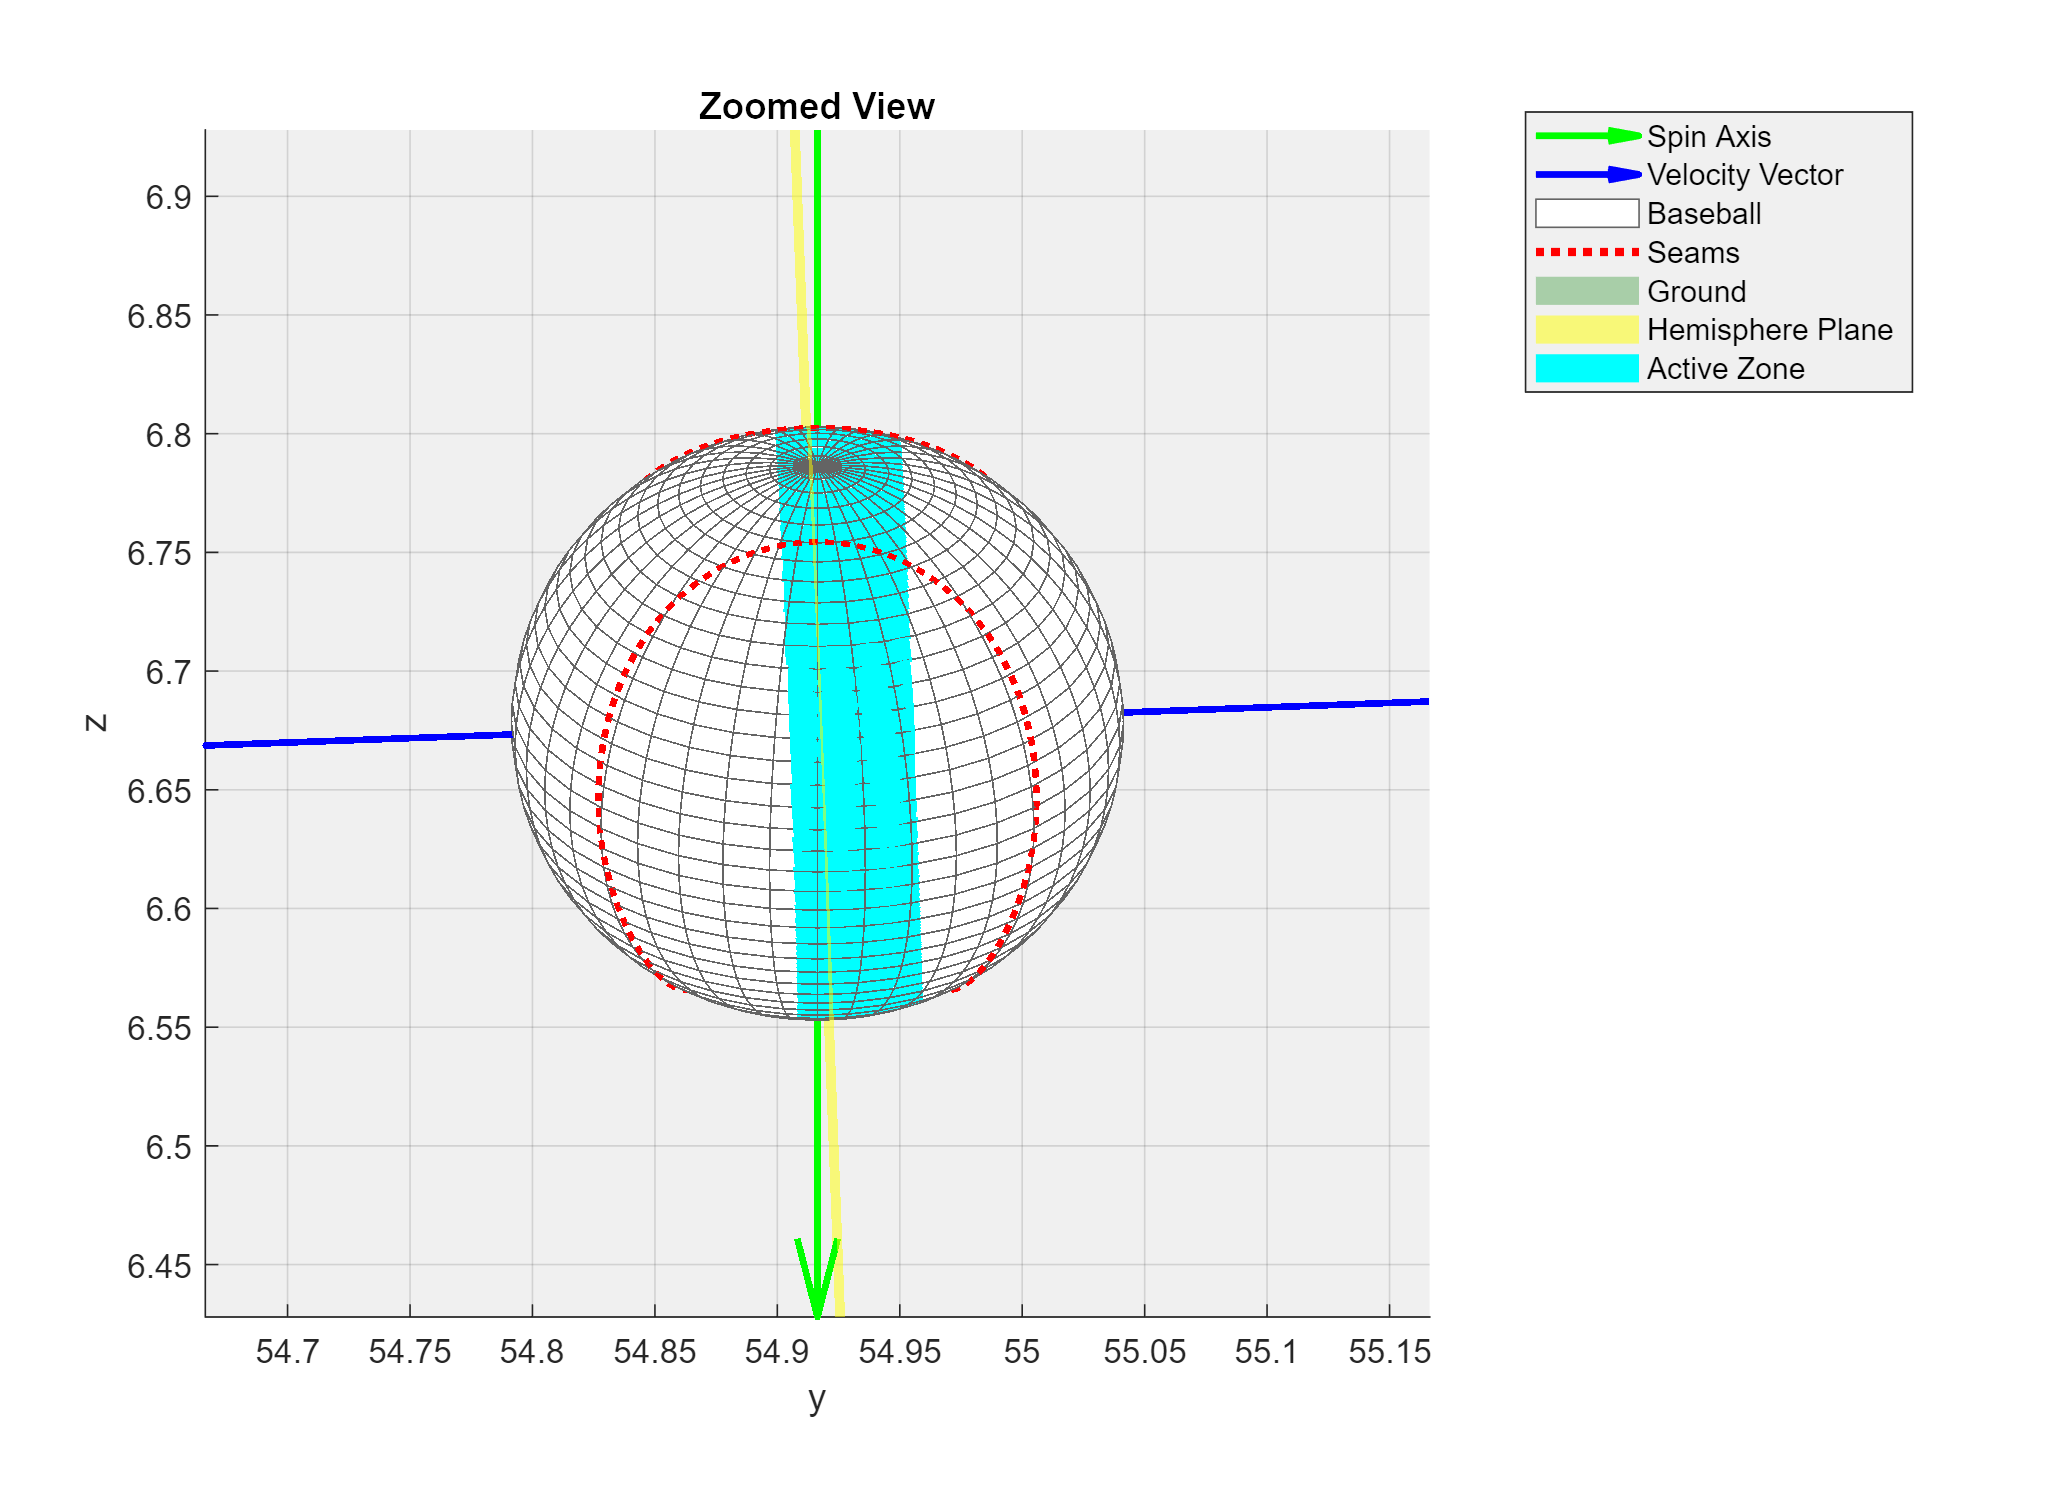

% Section break to get a second plot

% Zoom in to the baseball
title('Zoomed View')
xlim([center(1) - diameter center(1) + diameter]);
ylim([center(2) - diameter center(2) + diameter]);
zlim([center(3) - diameter center(3) + diameter]);

% Plot the hemisphere plane 
% The hemisphere plane and active zone are defined in the paper 'Using baseball seams to alter a pitch
% direction: The seam shifted wake'
surf(hemisphere_x, hemisphere_y, hemisphere_z, 'EdgeColor', 'none', 'FaceColor', 'y', 'FaceAlpha', 0.5);

% Calculate the active zone
% Get the position that points to negative y axis first, then rotate to the velocity vector

% Calculate the point at the middle of the back plane using the velocity
% vector
distance1 = ball_radius*sin(18*pi/180); % Get the distance between center of the ball and the back plane

% Calculate the point at the middle of the front plane using the velocity
% vector
distance2 = ball_radius*sin(6*pi/180); % Get the distance between center of the ball and the front plane

% Obtain the upperbound and lowerbound for y
y_upperbound = center(2) + distance1;
y_lowerbound = center(2) - distance2;

% Plot the active zone
[X_az, Y_az, Z_az] = sphere(1000);
X_az = double(center(1) + ball_radius*X_az);
Y_az = double(center(2) + ball_radius*Y_az);
Z_az = double(center(3) + ball_radius*Z_az);
Y_az(Y_az < y_lowerbound) = NaN; % Remove redundant parts of the sphere
Y_az(Y_az > y_upperbound) = NaN; 
az = surf(X_az, Y_az, Z_az);
az.FaceColor = 'cyan';
az.EdgeColor = 'none'; % Grid color
az.FaceAlpha = 1.0; % Transparency
legend('Spin Axis', 'Velocity Vector', 'Baseball', 'Seams', 'Ground', 'Hemisphere Plane', 'Active Zone')

% Rotate the strip to align the velocity vector with the negative y axis
negative_y = [0, -1, 0];

% Get the rotation angle and vector, consider different cases
dot_product = dot(negative_y, v_vector);
cross_product = cross(negative_y, v_vector);
if dot_product == 1
    rotation_theta = 0;
elseif dot_product == -1
    rotation_theta = pi;
    rotate(az, [0, 0, 1], rotation_theta, center); % Rotate around z axis
else
    if dot_product >= 0
        rotation_theta = asind(norm(cross_product));
    elseif dot_product < 0
        rotation_theta = pi - asind(norm(cross_product));
    end
    rotate_vector = cross_product/norm(cross_product); % Normalize
    rotate(az, rotate_vector, rotation_theta, center); % Rotate
end